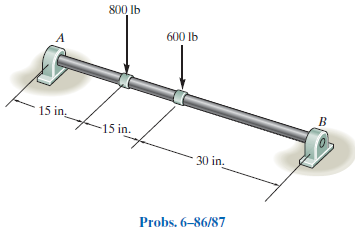

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-86P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-86P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 60*u.in);
b = b.add('concentrated', 'force', -800*u.lbf, 15*u.in);
b = b.add('concentrated', 'force', -600*u.lbf, 30*u.in);
b.L = 60*u.in;

# section properties

D = 2*u.in;
b.I = sympi/4*(D/2)^4;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{600\,x\,\left(1950\,{\mathrm{in}}^{2}-x^{2}\right)}{\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 15\,\mathrm{in}\\ \frac{200\,\left(x^{3}+360\,x^{2}\,\mathrm{in}-22950\,x\,{\mathrm{in}}^{2}+27000\,{\mathrm{in}}^{3}\right)}{3\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\in \left(15\,\mathrm{in},30\,\mathrm{in}\right]\\ -\frac{1000\,\left(x-60\,\mathrm{in}\right)\,\left(x^{2}-120\,x\,\mathrm{in}+630\,{\mathrm{in}}^{2}\right)}{3\,\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }30\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{1800\,\left(650\,{\mathrm{in}}^{2}-x^{2}\right)}{\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 15\,\mathrm{in}\\ \frac{200\,\left(x^{2}+240\,x\,\mathrm{in}-7650\,{\mathrm{in}}^{2}\right)}{\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }x\in \left(15\,\mathrm{in},30\,\mathrm{in}\right]\\ -\frac{1000\,\left(x^{2}-120\,x\,\mathrm{in}+2610\,{\mathrm{in}}^{2}\right)}{\text{E}\,\pi }\,\frac{\mathrm{lbf}}{{\mathrm{in}}^{4}} & \text{ if }30\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 900\,x\,\mathrm{lbf} & \text{ if }x\leq 15\,\mathrm{in}\\ 100\,\left(x+120\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }x\in \left(15\,\mathrm{in},30\,\mathrm{in}\right]\\ -500\,\left(x-60\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }30\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 900\,\mathrm{lbf} & \text{ if }x\leq 15\,\mathrm{in}\\ 100\,\mathrm{lbf} & \text{ if }x\in \left(15\,\mathrm{in},30\,\mathrm{in}\right]\\ -500\,\mathrm{lbf} & \text{ if }30\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 900\,\mathrm{lbf}\\ \mathrm{Rb} & 500\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and bending moment diagram

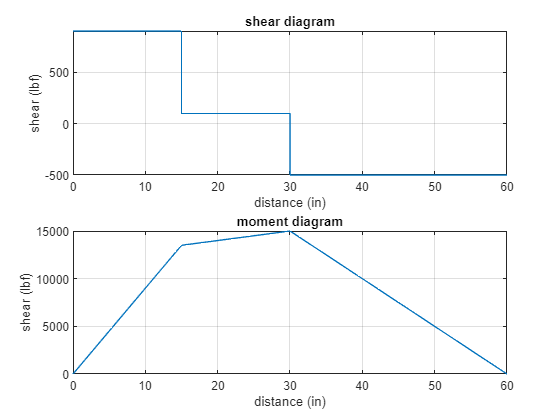

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# maximum bending stress

M_max = m(b.L/2)

$$M\_max = 15000\,\mathrm{in}\,\mathrm{lbf}$$

C = D/2;
sigma_max = rewrite(M_max*C/b.I, u.ksi);
sigma_max_vpa = vpa(sigma_max, 4)

$$sigma\_max\_vpa = 19.1\,\mathrm{ksi}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;